clear all
rng(1); % for reproducibility, added before final github upload however
data = readtable("G20CrNi2Mo Bearing Steel Data_Zhao.xlsx");

%data.Properties.VariableNames
%unique(data.ContactStressAmplitude_MPa_);
%groupcounts(data, "ContactStressAmplitude_MPa_"); 

S_data = data.ContactStressAmplitude_MPa_;
N_data = data.NumberOfCycles;

% quantile regression to get the median relationship at the nominal stresses

log_stress_data = log10(S_data);
Y = log10(N_data);

% matlab checks because of issues with quantile reg
%size(log_stress_data)
%size(log_life_data)
%[min(log_stress_data) max(log_stress_data)]
%[min(log_life_data) max(log_life_data)]
%corrcoef(log_stress_data, log_life_data)

% linear quantile regression for 50% quantile, which gives B50 (distribution-less)
mdl = fitrqlinear(log_stress_data, Y, Quantiles=0.50, Lambda=0,Standardize=true, BetaTolerance=1e-6) % order matters here, the predictor is the log-stress and the response is log-life

mdl =   RegressionQuantileLinear
             ResponseName: 'Y'
    CategoricalPredictors: []
        ResponseTransform: 'none'
                     Beta: -0.3828
                     Bias: 7.7525
                Quantiles: 0.5000



slope_coefficient = mdl.Beta

slope_coefficient = -0.3828

intercept = mdl.Bias

intercept = 7.7525

mdl.ConvergenceInfo % required because of convergence issues, had to include standardize = true for proper run

ans = struct with fields:
                  Lambda: 0
               Objective: 0.2050
          IterationLimit: 1000
           NumIterations: 8
            GradientNorm: 3.6097e-18
       GradientTolerance: 1.0000e-06
    RelativeChangeInBeta: 4.2730e-04
           BetaTolerance: 1.0000e-06
         TerminationCode: 2
       TerminationStatus: {'Tolerance on gradient satisfied.'}
                 History: []
                 FitTime: 0.0609



% generate the B50 Y points 
B50_predictions = predict(mdl, log_stress_data); % to ensure s-n curve matches up with data, due to standardise


% 
residuals = Y - B50_predictions;
sigma_e = std(residuals)

sigma_e = 0.5117

CoV_Lognormal_theoretical = sqrt(exp((log(10)*sigma_e)^2) - 1)

CoV_Lognormal_theoretical = 1.7343

N_MC = 500000;
COV_S = 0.01; % for stress CoV = 1%

% All stress levels
stress_levels = unique(S_data);
num_stress_levels = numel(stress_levels);

% Store results separately for each stress level
B1_Weibull_all = zeros(num_stress_levels, 1);
B1_Lognormal_all = zeros(num_stress_levels, 1);

N_Weibull_all = cell(num_stress_levels, 1);
N_Lognormal_all = cell(num_stress_levels, 1);
S_sim_all = cell(num_stress_levels, 1);

%% 6. FIT THE RESIDUAL DISTRIBUTIONS

% Lognormal fatigue-life model: normal log-life residuals
mu_eps = mean(residuals);
sigma_eps = std(residuals);

% weibull fatigue-life model: minimum extreme-value residuals
% evfit fits the minimum extreme-value distribution
params_ev = evfit(residuals);
mu_ev = params_ev(1);  
sigma_ev = params_ev(2); 

% 1st percentile of each residual distribution
q01_Lognormal = norminv(0.01, mu_eps, sigma_eps);
q01_Weibull =  evinv(0.01, mu_ev, sigma_ev);


Stress level: 4900 MPa


Lognormal B1 life: 1.2651e+07 cycles


Weibull B1 life:   3.0294e+06 cycles


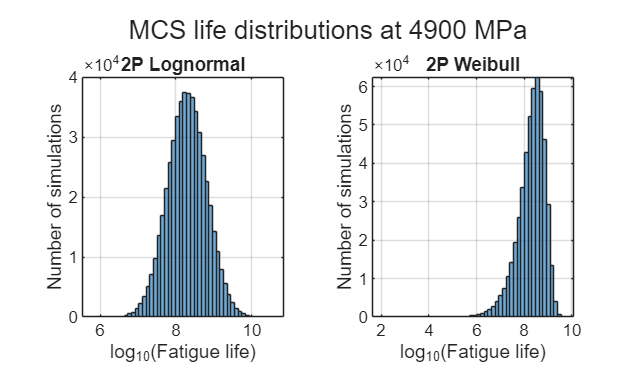


Stress level: 5500 MPa


Lognormal B1 life: 5.3509e+06 cycles


Weibull B1 life:   1.2444e+06 cycles


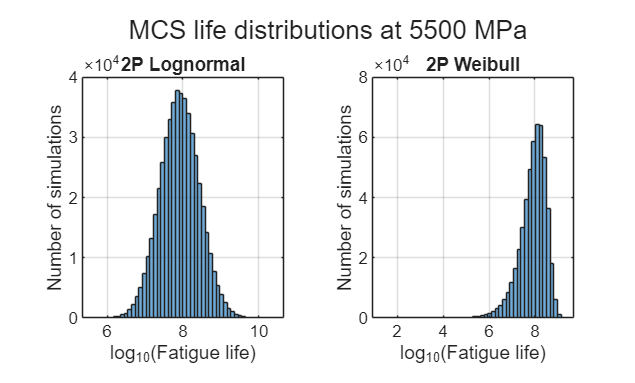


Stress level: 6100 MPa


Lognormal B1 life: 2.4640e+06 cycles


Weibull B1 life:   5.8241e+05 cycles


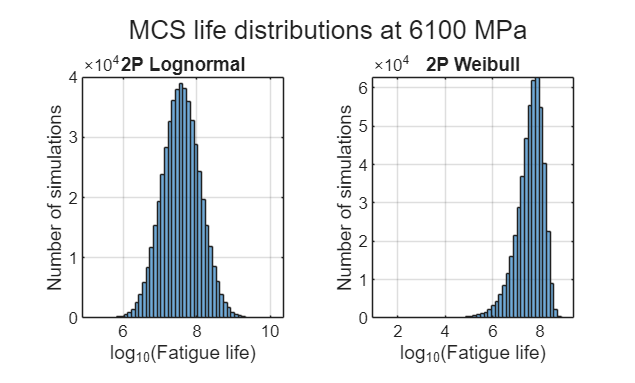


Stress level: 6700 MPa


Lognormal B1 life: 1.2187e+06 cycles


Weibull B1 life:   2.9213e+05 cycles


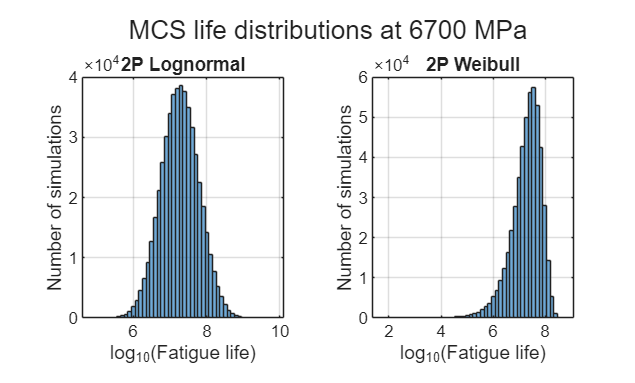

for s = 1:num_stress_levels

    S_nom = stress_levels(s);
    sigma_S = COV_S * S_nom;
    fprintf('\nStress level: %.0f MPa\n', S_nom);
    % Generate uncertain stress inputs
    S = normrnd(S_nom, sigma_S, N_MC, 1);

    % Ensure stress remains positive
    S(S <= 0) = eps;
    % evaluate the global median S-N relationship
    Y_median = predict(mdl, log10(S));
    % generate log-life residuals for each model
    epsilon_Lognormal = normrnd(mu_eps, sigma_eps, N_MC, 1);
    epsilon_Weibull = evrnd(params_ev(1), params_ev(2), N_MC, 1);

    % Calculate log-life
    Y_Lognormal = Y_median + epsilon_Lognormal;
    Y_Weibull = Y_median + epsilon_Weibull;

    % Convert log-life to cycles
    N_Lognormal = 10.^Y_Lognormal;
    N_Weibull = 10.^Y_Weibull;

    % Calculate B1 life
    B1_Lognormal_all(s) = prctile(N_Lognormal, 1);
    B1_Weibull_all(s) = prctile(N_Weibull, 1);
    N_Lognormal_all{s} = N_Lognormal;
    N_Weibull_all{s} = N_Weibull;
    S_sim_all{s} = S;

    fprintf('Lognormal B1 life: %.4e cycles\n', B1_Lognormal_all(s));
    fprintf('Weibull B1 life:   %.4e cycles\n', B1_Weibull_all(s));
    % histrograms for both distributions side by side
    figure; 
    tiledlayout(1, 2);
    nexttile;
    histogram(log10(N_Lognormal), 50);
    xlabel('log_{10}(Fatigue life)');
    ylabel('Number of simulations');
    title('2P Lognormal');
    grid on;

    nexttile;
    histogram(log10(N_Weibull), 50);
    xlabel('log_{10}(Fatigue life)');
    ylabel('Number of simulations');
    title('2P Weibull');
    grid on;

    sgtitle(sprintf('MCS life distributions at %.0f MPa', S_nom));

end

% table for mcs results
MCS_results = table(stress_levels, compose('%.4e', B1_Lognormal_all),compose('%.4e', B1_Weibull_all), ...
    'VariableNames', {'Hertzian contact stress amplitude (MPa)', 'B1 life 2-P Lognormal', 'B1 life 2-P Weibull'});

writetable(MCS_results, 'MCS_lives.txt', 'Delimiter', '\t');


## Plotting Results 

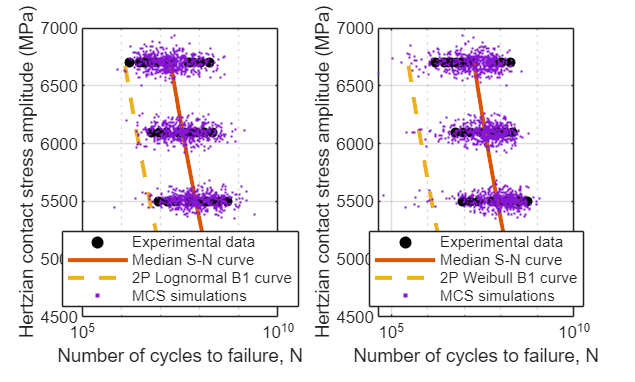

figure;
tiledlayout(1, 2);

S_plot = linspace(min(S_data), max(S_data), 200)';

% Median S-N predictions
Y_median_plot = predict(mdl, log10(S_plot));

% B1 curves for each residual model
Y_B1_Lognormal = Y_median_plot + q01_Lognormal;
Y_B1_Weibull = Y_median_plot + q01_Weibull;

% Convert predicted log-life to actual fatigue life
N_median_plot = 10.^Y_median_plot;
N_B1_Lognormal = 10.^Y_B1_Lognormal;
N_B1_Weibull = 10.^Y_B1_Weibull;

% Combine simulation results from all stress levels
N_Lognormal_combined = vertcat(N_Lognormal_all{:});
N_Weibull_combined = vertcat(N_Weibull_all{:});
S_combined = vertcat(S_sim_all{:});

% Plot only a subset of simulated observations to keep the diagrams legible
num_plot = min(2000, numel(S_combined));
idx_plot = round(linspace(1, numel(S_combined), num_plot));

% lognormal S-N diagram
nexttile;
hold on;
grid on;
box on;
scatter(N_data, S_data, 25, 'k', 'filled');
plot(N_median_plot, S_plot, 'LineWidth', 2);
plot(N_B1_Lognormal, S_plot, '--', 'LineWidth', 2);
scatter(N_Lognormal_combined(idx_plot), S_combined(idx_plot), 8, '.');
set(gca, 'XScale', 'log');
xlabel('Number of cycles to failure, N');
ylabel('Hertzian contact stress amplitude (MPa)');
legend('Experimental data', 'Median S-N curve', ...
    '2P Lognormal B1 curve', 'MCS simulations', 'Location', 'best');
hold off;

% weibull S-N diagram

nexttile;
hold on;
grid on;
box on;
scatter(N_data, S_data, 25, 'k', 'filled');
plot(N_median_plot, S_plot, 'LineWidth', 2);
plot(N_B1_Weibull, S_plot, '--', 'LineWidth', 2);
scatter(N_Weibull_combined(idx_plot), S_combined(idx_plot), 8, '.');
set(gca, 'XScale', 'log');
xlabel('Number of cycles to failure, N');
ylabel('Hertzian contact stress amplitude (MPa)');
legend('Experimental data', 'Median S-N curve', ...
    '2P Weibull B1 curve', 'MCS simulations', 'Location', 'best');
hold off;